# 光标控制

### 载入指令动作识别模型

clear;
clc;

%确定路径
cd 'C:\Users\zkc\Desktop'
codepath=pwd;

%实时数据文件
filename='data.log';

%载入模型
load("Model.mat")

### 调用JAVA以控制鼠标

%% 调用javaRobot类
javaaddpath('D:\Java\jdk-22.0.1\bin')  %文件相对路径
import java.awt.Robot;
import java.awt.event.*;
import java.awt.event.InputEvent;
% 创建Robot对象
robot = Robot();

### 定义模型参数

%采样信息
T=250;

%Matlab每次读取数据的间隔时间
read_intervals = 0.2;

%读取测试数据的框选参数
frame_T=10;        %在数据上框选子数据的频率
frame_move=25;     %节选框每次移动的距离
frame_length=700;  %框的大小
frame_energy=0.2;    %眼动能量达到此阈值才开始启动模型（范围是0-1）
frame_varience = 0.6; %判定是否眼动的信号方差大小
frame_interval=1;%（不应期）识别得到一个指令信号后，为了防止同一个指令动作被反复识别，间隔多长时间重新开始裁剪数据

%鼠标的移动参数
mouse_T=10;        %鼠标每秒移动的次数
mouse_move=10;     %鼠标每次移动的距离
mouse_temp = 0.5;  %鼠标是否停顿的阈值

%滤波参数
level = 5; % 小波变换的层数，可根据实际情况调整
wname = 'db4'; % 小波类型，可根据实际情况选择
alpha=1.5;%阈值倍数


### 创建一个窗口

% 创建一个 Figure
f = figure('KeyPressFcn', @keyCallback);
%方便用ESC退出程序

### 主程序

#### 主程序流程图：

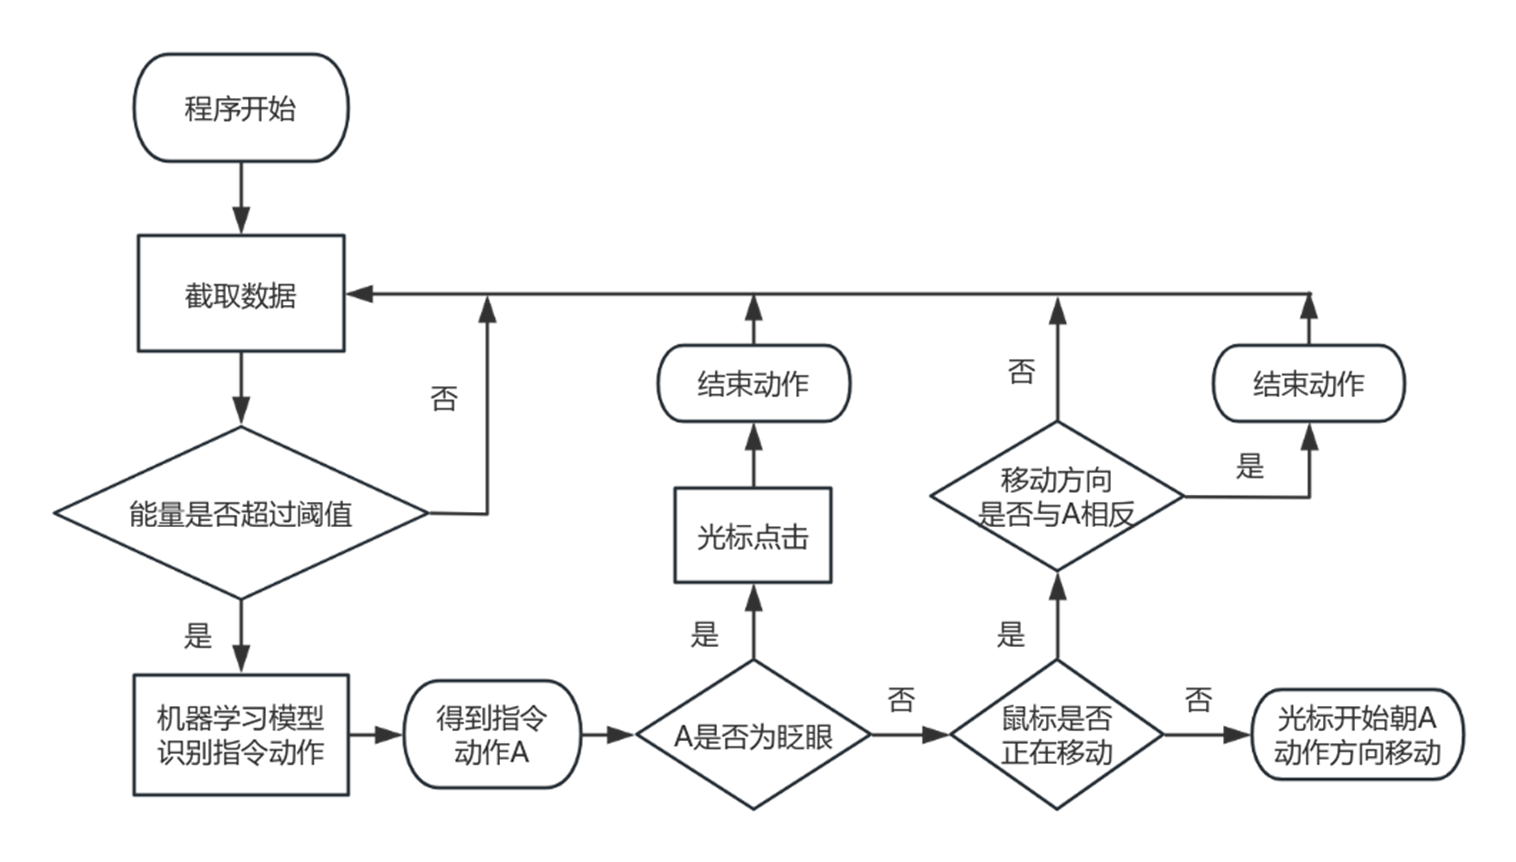

#### 初始化主程序相关参数：

%记录鼠标的状态（是静止，还是上下左右或眨眼）
Cursor_status = 0; %0是静止，1是上，2是下，3是右，4是左,5是眨眼

%电信号相关参数
start=1; %从eog的start位置开始裁剪数据
time=[-1,-1];%指令动作在eog上的位置

%不应期
refractory_time=0;%不应期的累计时间
refractory_key=1;%是否已度过不应期

%距离上一次MATLAB读取数据过去了多久
read_time=0;

%主程序是否终止
key=0;%eog数据读取到头，则程序终止
data_size=0;%记录实时文件的长度

#### **读入初始Jlink数据**

input_MAX=1000;

%初始Jlink数据长度
Jlink_length = 0;

while Jlink_length<(input_MAX*2)
    %% 读取文件，匹配列表
    fid=fopen(filename);

    %跳过前三行
    textscan(fid, '%*[^\n]', 3);
    
    data=textscan(fid,'%s %f');
    fclose(fid);
    
    %获取长度
    Jlink_length=size(data{2},1);
    
    clear data fid;

    %等待一秒
    pause(1);
end

%% 读取文件，匹配列表
fid=fopen(filename);

%跳过前三行
textscan(fid, '%*[^\n]', 3);
    
data=textscan(fid,'%s %f');

fclose(fid);

Jlink_data = [];  % 初始化存放结果的矩阵

data_size = size(data{2},1);

%%
length=zeros(1,2);
lab={'01>','00>'};%注意1、2号通道被倒置

%%初始化载入的数据
for i = (numel(data{2})-(2*input_MAX)):numel(data{2})
    if isequal(data{1}(i),lab(1)) 
        Jlink_data(length(1)+1,1)= data{2}(i);
        length(1)=length(1)+1;

    elseif isequal(data{1}(i),lab(2))
        Jlink_data(length(2)+1,2)= data{2}(i);
        length(2)=length(2)+1;
    end

end

clear data fid Jlink_length;

#### 读取数据并做出反应

while ~key %判断程序是否要终止
    %开始计时
    tic;

% % % % % % % % % % % % % % % % % %根据鼠标现在的状态，作出动作
    switch Cursor_status 

        %鼠标不动
        case 0

            %不动
            %pause(1/mouse_T);


        %鼠标向上
        case 1

            %获取鼠标位置
            [x,y]=mouse_position();
            % 将鼠标向上移动mouse_move个像素
            robot.mouseMove(x, y-mouse_move);
            %控制鼠标每秒的移动次数
            %pause(1/mouse_T);


        %鼠标向下
        case 2 

            %获取鼠标位置
            [x,y]=mouse_position();
            % 将鼠标向上移动mouse_move个像素
            robot.mouseMove(x, y+mouse_move);
            %控制鼠标每秒的移动次数
            %pause(1/mouse_T);


        %鼠标向右移动
        case 3 

            %获取鼠标位置
            [x,y]=mouse_position();
            % 将鼠标向上移动mouse_move个像素
            robot.mouseMove(x+mouse_move, y);
            %控制鼠标每秒的移动次数
            %pause(1/mouse_T);


        %鼠标向左移动
        case 4 

            %获取鼠标位置
            [x,y]=mouse_position();
            % 将鼠标向上移动mouse_move个像素
            robot.mouseMove(x-mouse_move, y);
            %控制鼠标每秒的移动次数
            %pause(1/mouse_T);


        %眨眼
        case 5

            %鼠标点击

            robot.mousePress(java.awt.event.InputEvent.BUTTON1_MASK);
            robot.delay(100);
            robot.mouseRelease(java.awt.event.InputEvent.BUTTON1_MASK);
            %鼠标状态变回静止
            Cursor_status=0;
            %pause(1/mouse_T);

    end



% % % % % % % % % % % % % % % % % 鼠标状态改变
    if Cursor_status == 0||1||2||3||4

       %达到不应期时间，累计时间归0，refractory_key变为1，更新裁剪的start位置
       if refractory_time >= frame_interval
           
           %此处默认不应期的时间大于每次读取数据的间隔时间
           %过了不应期之后，从Jlink_data的第一位开始读取数据
           start = 1;

           refractory_key=1;
           refractory_time=0;

       end


       %若还未过不应期，则继续累计时间;若到达则裁剪下一个片段、

       %累计不应期时间
       if refractory_key==0
           refractory_time = refractory_time + 1/mouse_T;
       
       %不处在不应期且读取框还在Jlink_data内
       elseif refractory_key==1 && (start + frame_length)< input_MAX

            %[cut_data, time] = cutEOG(Jlink_data, start, frame_length, frame_energy);
            [cut_data, time] = cutEOG(Jlink_data, start, frame_length, frame_varience);
            start=min(input_MAX,start+frame_move);
            
            %cut_data
            
            %下一个片段达到能量阈值
            if time(1,2)~=-1
                wavelet_data=WaveLet(cut_data, level, wname, alpha);
                features_data=real(Features(wavelet_data));
                pre_label=str2num(char(cell2mat(model.predict(features_data))))
                
                if Cursor_status == 0
                    %鼠标为静止状态时，可变为任意状态
                    Cursor_status =pre_label;
                    %不应期状态归零，重新进入不应期
                    refractory_key=0;

                elseif Cursor_status ~= 0 && Cursor_status == pre_label
                    %指令动作与鼠标状态相反，恢复静止状态
                    Cursor_status = 0;
                    %不应期状态归零，重新进入不应期
                    refractory_key=0;

                end
            end
       end
    end



    %累计时间
    temp = toc;

    if temp < mouse_temp
        pause(1/mouse_T);
    end

    read_time = read_time + temp;

    tic;
    
% % % % % % % % % % % % % % % %更新数据
    if read_time > read_intervals
        read_time=0;
        
        %% 读取文件，匹配列表
        fid=fopen(filename);
        
        %跳过前三行
        textscan(fid, '%*[^\n]', 3);
            
        data=textscan(fid,'%s %f');
        
        fclose(fid);
        
% % % % % % % % % % % % % % % %终止程序的条件
        %若新数据与原来的数据相同，则终止
        new_data_size = size(data{2},1);

        if data_size == new_data_size
            key=1;
        else
            data_size = new_data_size;
        end
        
        new_data = [];  % 存放新数据

        %%载入新数据
        lab={'01>','00>'};
        length=zeros(1,2);
        
        %%初始化载入的数据
        for i = (numel(data{2})-2*(T*read_intervals)+1):numel(data{2})

            if isequal(data{1}(i),lab(1)) 
                new_data(length(1)+1,1)= data{2}(i);
                length(1)=length(1)+1;
        
            elseif isequal(data{1}(i),lab(2))
                new_data(length(2)+1,2)= data{2}(i);
                length(2)=length(2)+1;

            end
        
        end

        %更新Jlink_data
        Jlink_data = [Jlink_data(T*read_intervals+1:end,1:2);new_data];%长度保持为2000

        clear data fid new_data;

        %更新新的start读取位置
        start = max(start-T*read_intervals,1);%更新start可能出现低于0的情况，低于0的置0

    end

    read_time = read_time + toc;

end

pre_label = 3

pre_label = 3

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 5

pre_label = 2

pre_label = 3

pre_label = 2

pre_label = 4

pre_label = 2

pre_label = 2

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 3

pre_label = 3

pre_label = 3

pre_label = 3

pre_label = 3

pre_label = 2

pre_label = 3

pre_label = 3

pre_label = 3

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 2

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 2

pre_label = 1

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 3

pre_label = 3

pre_label = 3

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 5

pre_label = 3

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

pre_label = 4

## 函数

#### 强制退出

function keyCallback(~, event)
    % 检测键盘按键事件，按下 ESC 键时终止程序
    if strcmp(event.Key, 'escape')
        close(gcf); % 关闭图形窗口
        exit();
    end
end

#### 获得满足条件的备选信号

%cut_data是符合条件的裁剪数据，time为此片段在eog上的位置
%如果没有符合条件的数据，time返回[-1,-1];cut_data返回[-1,-1]

% % % % % % % % % % % %旧版函数
% function [cut_data, time] = cutEOG(eog, start, frame_length, frame_energy)
% 
%     % 每个裁剪片段的距离（长度）
%     samples_per_frame = frame_length;
% 
%     % 初始化符合条件的数据和时间坐标
%     cut_data = [];
%     time = zeros(1,2);
%     % 初始化当前位置
%     current_pos = start;
%     
%     % 根据当前位置获取裁剪片段的起始和结束位置
%     frame_start = current_pos;
%     frame_end = frame_start + samples_per_frame - 1;
%         
%     if frame_end > size(eog, 1)
%         % 当 frame_end 超过 eeg 数据总样本数时，终止循环
%         cut_data=[-1,-1];
%         time(1,1)=-1;
%         time(1,2)=-1;
%         return
%     end
%         
%     %将数据归一化
%     % 计算每一列的最小值和最大值
%     min_val = min(eog(frame_start:frame_end, :));
%     max_val = max(eog(frame_start:frame_end, :));
% 
%     % 计算每一列的范围
%     range = max_val - min_val;
% 
%     % 对每一列进行归一化
%     normalized_data = (eog(frame_start:frame_end, :) - min_val) ./ range;
%         
%     % 计算当前裁剪片段的能量
%     frame_energy_values = sum(abs(normalized_data(:,:) ).^2) / samples_per_frame;
%         
%     % 判断当前裁剪片段的每一列能量是否满足阈值
%     if frame_energy_values(1) >= frame_energy && frame_energy_values(2) >= frame_energy
%        cut_data =normalized_data;
%        time(1,1)=frame_start;
%        time(1,2)=frame_end;
%        %disp('裁剪');
% 
%        %此片段不符合条件，则返回-1
%     else
%         time(1,1)=-1;
%         time(1,2)=-1;
%         cut_data=[-1,-1];
%     end
%     
% end

% % % % % % % % % % % %新版函数
function [cut_data, time] = cutEOG(eog, start, frame_length, frame_varience)

    % 初始化符合条件的数据和时间坐标
    cut_data = [];
    time = zeros(1,2);
    
    % 根据当前位置获取裁剪片段的起始和结束位置
    frame_start = start;
    frame_end = frame_start + frame_length - 1;
        
    if frame_end > size(eog, 1)
        % 当 frame_end 超过 eeg 数据总样本数时，终止循环
        cut_data=[-1,-1];
        time(1,1)=-1;
        time(1,2)=-1;
        return
    end

    % 判断当前裁剪片段的每一列能量是否满足阈值
    if var(eog(frame_start:frame_end,1)) >= frame_varience && var(eog(frame_start:frame_end,2)) >= frame_varience
      
       %将数据归一化
       % 计算每一列的最小值和最大值
       min_val = min(eog(frame_start:frame_end, :));
       max_val = max(eog(frame_start:frame_end, :));
    
       % 计算每一列的范围
       range = max_val - min_val;
    
       % 对每一列进行归一化
       normalized_data = (eog(frame_start:frame_end, :) - min_val) ./ range;  

       cut_data =normalized_data;
       time(1,1)=frame_start;
       time(1,2)=frame_end;
       %disp('裁剪');

       %此片段不符合条件，则返回-1
    else
        time(1,1)=-1;
        time(1,2)=-1;
        cut_data=[-1,-1];
    end

end

#### 滤波函数：

%小波变换，返回滤波后的数据
function wavelet_data=WaveLet(cut_data, level, wname, alpha)

    wavelet_data=[];
    
    sig_afterLPF=cut_data;
    
    %进行小波变换
    for i=1:1:(size(sig_afterLPF,2)/2)%这个数据只有两列，但是为了防止多列数据出现，所以用了size来计算
    
        sig_afterLPF(:,2*i-1) = (sig_afterLPF(:,2*i-1) - mean(sig_afterLPF(:,2*i-1))) / std(sig_afterLPF(:,2*i-1));
        [a1, l1] = wavedec(sig_afterLPF(:,2*i-1), level, wname);
        thr1 = alpha*sqrt(2*log(length(sig_afterLPF(:,2*i-1))))*median(abs(a1)) / 0.6745;
        sig_afterLPF(:,2*i) = (sig_afterLPF(:,2*i) - mean(sig_afterLPF(:,2*i))) / std(sig_afterLPF(:,2*i));
        [a2, l2] = wavedec(sig_afterLPF(:,2*i), level, wname);
        thr2 = alpha*sqrt(2*log(length(sig_afterLPF(:,2*i))))*median(abs(a2)) / 0.6745;
        s1 = wthresh(a1, 's', thr1);
        s1 = waverec(s1, l1, wname);
        s2 = wthresh(a2, 's', thr1);
        s2 = waverec(s2, l2, wname);
    
        wavelet_data=[wavelet_data,s1];
    
        wavelet_data=[wavelet_data,s2];
    
    end

end

#### 提取特征：

%提取裁剪信号的特征值
%最后的得到的features_data为一行18个特征值的数据

function features_data=Features(wavelet_data)

    data=wavelet_data;
    
    % 获取数据列数
    num_columns = size(data, 2);
    
    % 初始化特征矩阵
    features_data = zeros(num_columns/2 , 2 * 9); % 9是时域和频域特征的总数
    
    % 循环处理每两列数据
    for i = 1:2:num_columns%和滤波数据一样，防止出现多个列，所以用了size
        % 提取一对数据
        temp=[];
    
        channel1 = data(:, i);
        channel2 = data(:, i + 1);
    
        % 时域特征
        rms_value = rms(channel1);
        temp=[temp,rms_value];
        rms_value = rms(channel2);
        temp=[temp,rms_value];
    
        mav_value = mean(abs(channel1));
        temp=[temp,mav_value];
        mav_value = mean(abs(channel2));
        temp=[temp,mav_value];
    
        var_value = var(channel1);
        temp=[temp,var_value];
        var_value = var(channel2);
        temp=[temp,var_value];
    
        zc_value = sum(abs(diff(sign(channel1)))) / (length(channel1) - 1);
        temp=[temp,zc_value];
        zc_value = sum(abs(diff(sign(channel2)))) / (length(channel2) - 1);
        temp=[temp,zc_value];
    
        ssc_value = sum(abs(diff(sign(diff(channel1))))) / (length(channel1) - 2);
        temp=[temp,ssc_value];
        ssc_value = sum(abs(diff(sign(diff(channel2))))) / (length(channel2) - 2);
        temp=[temp,ssc_value];
    
        % 频域特征
        fft_result1 = fft(channel1);
        fft_result2 = fft(channel2);
    
        am_value = mean(abs(fft_result1));
        temp=[temp,am_value];
        am_value = mean(abs(fft_result2));
        temp=[temp,am_value];
    
        % 计算幅度谱  
        amp_spec = abs(fft_result1);  
        % 归一化幅度谱  
        amp_spec = amp_spec / sum(amp_spec);  
        % 计算质心  
        centroid = sum(amp_spec .* fft_result1);  
        % 计算质心频率
        Fs=250;
        centroid_freq = centroid * (Fs / 2);
        cf_value = centroid_freq;
        temp=[temp,cf_value];
    
        % 计算幅度谱  
        amp_spec = abs(fft_result2);  
        % 归一化幅度谱  
        amp_spec = amp_spec / sum(amp_spec);  
        % 计算质心  
        centroid = sum(amp_spec .* fft_result2);  
        % 计算质心频率
        Fs=250;
        centroid_freq = centroid * (Fs / 2);
        cf_value = centroid_freq;
        temp=[temp,cf_value];
    
        fvar_value = var(abs(fft_result1));
        temp=[temp,fvar_value];
        fvar_value = var(abs(fft_result2));
        temp=[temp,fvar_value];
    
        mdf_value = meanfreq(channel1);
        temp=[temp,mdf_value];
        mdf_value = meanfreq(channel2);
        temp=[temp,mdf_value];
    
        features_data((i+1)/2,:) = temp;
    end

end

#### 获取鼠标位置

function [x,y]=mouse_position()
    mouseInfo = java.awt.MouseInfo.getPointerInfo();
    mouseLocation = mouseInfo.getLocation();
    x = mouseLocation.getX();
    y = mouseLocation.getY();
end